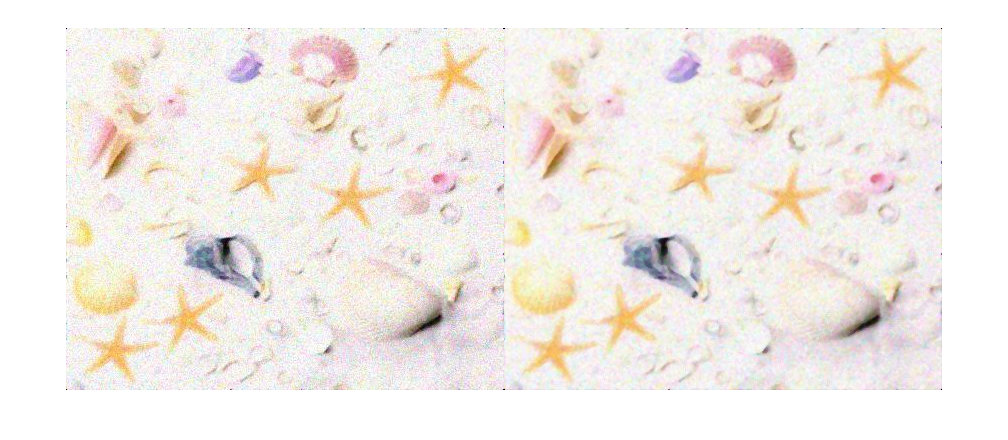

oImage = imread('images/starfish_noise7.jpg');
[rows, columns, numberOfColorBands] = size(oImage);


% figure
% rconv2 = uint8(conv2(1/(4 * 4) * ones(4), oImage(:,:,1)));
% histogram(rconv2);
% gconv2 = uint8(conv2(1/(4 * 4) * ones(4), oImage(:,:,2)));
% histogram(gconv2);
% bconv2 = uint8(conv2(1/(4 * 4) * ones(4), oImage(:,:,3)));
% histogram(bconv2);

figure
rmedfilt2 = medfilt2(oImage(:,:,1));
gmedfilt2 = medfilt2(oImage(:,:,2));
bmedfilt2 = medfilt2(oImage(:,:,3));

% figure
% deSPImageRGBtoGray = medfilt2(rgb2gray(oImage));
% imshowpair(oImage,deSPImageRGBtoGray,'montage')

% figure
% deSPImageRGBByconv2= cat(3,rconv2, gconv2, bconv2);
% imshowpair(oImage,deSPImageRGBByconv2,'montage')

figure
deSPImageRGBBymedfilt2= cat(3,rmedfilt2, gmedfilt2, bmedfilt2);
imshowpair(oImage,deSPImageRGBBymedfilt2,'montage')

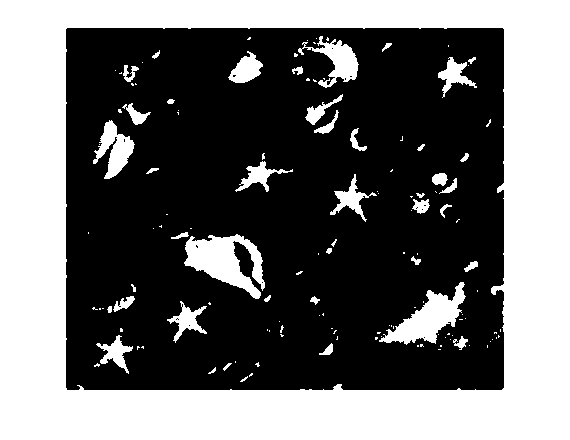



bestImage = deSPImageRGBBymedfilt2;

GrayImage = imcomplement(imbinarize(rgb2gray(bestImage)));

imshow(GrayImage)

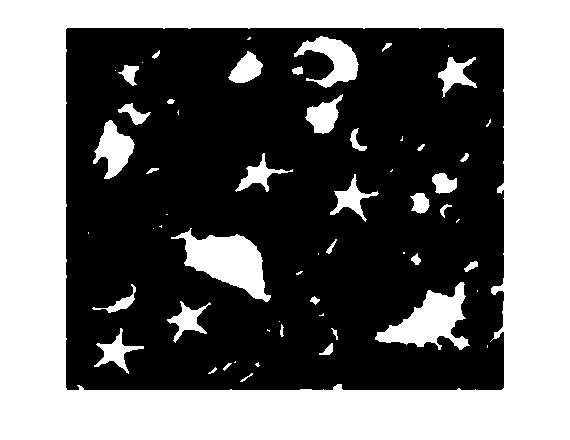

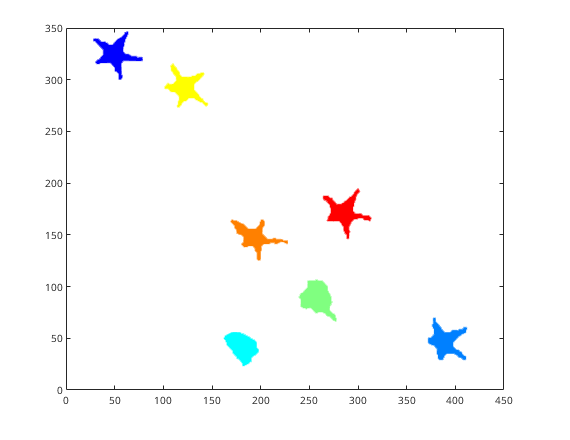


FilteredImage = imclose(GrayImage, strel('disk', 5));


FilteredImage = imfill(FilteredImage , 'holes');

imshow(FilteredImage)

[regions, cc] = detectMSERFeatures(FilteredImage, 'RegionAreaRange',[600,1200]);
plot(regions, 'showPixelList', true, 'showEllipses', false);

regrionProps = regionprops(cc, 'BoundingBox', 'Eccentricity', 'Solidity', 'Image', 'Area');

idx = [regrionProps.Eccentricity] > .5 & [regrionProps.Solidity] < .6

idx = 1×7 logical array
   1   1   0   0   1   1   1


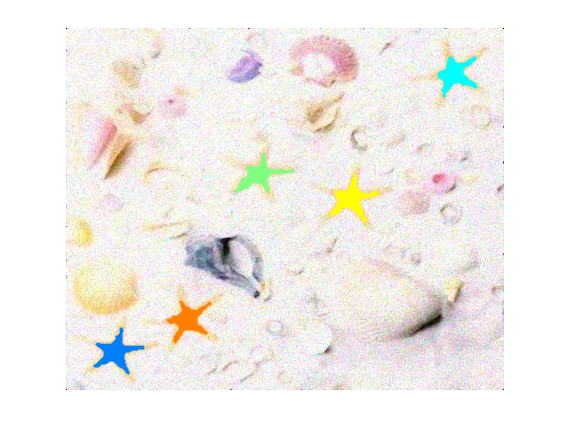


imshow(oImage)
hold on
plot(regions(idx), 'showPixelList', true, 'showEllipses', false);
hold off